% Unload data
data = readtable('AORD_2012_2022.xlsx');
y_original = data.Return;
y_mean = mean(y_original);
y_t = y_original-y_mean; % recenter

## 1 EDA

min_return = min(y_t);
max_return = max(y_t);
mean_return = mean(y_t);
std_return = std(y_t);

fprintf('Minimum Return: %.4f\n', min_return);

Minimum Return: -7.0784


fprintf('Maximum Return: %.4f\n', max_return);

Maximum Return: 4.4235


fprintf('Mean Return: %.4f\n', mean_return);

Mean Return: -0.0000


fprintf('Standard Deviation: %.4f\n', std_return);

Standard Deviation: 0.8805



skewness_return = skewness(y_t);
kurtosis_return = kurtosis(y_t);

fprintf('Skewness: %.4f\n', skewness_return);

Skewness: -0.9649


fprintf('Kurtosis: %.4f\n', kurtosis_return);

Kurtosis: 9.9521


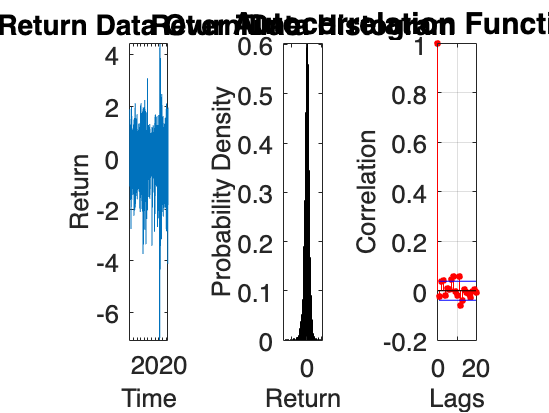


figure;
s1 = subplot(1, 3, 1);
plot(data.Date, y_t);
title('Return Data Over Time', 'FontSize', 20);
s1.FontSize = 17;
xlabel('Time', 'FontSize', 17);
ylabel('Return', 'FontSize', 17);

s2 = subplot(1, 3, 2);
histogram(y_t, 'Normalization', 'pdf');
title('Return Data Histogram', 'FontSize', 20);
s2.FontSize = 17;
xlabel('Return', 'FontSize', 17);
ylabel('Probability Density', 'FontSize', 17);

s3 = subplot(1, 3, 3);
autocorr(y_t);
s3.FontSize = 17;
title('Autocorrelation Function (ACF)', 'FontSize', 20);
xlabel('Lags', 'FontSize', 17);
ylabel('Correlation', 'FontSize', 17);

## 2 Parameter estimation

### 2.1 Markov Chain Monte Carlo

#### 2.1.1 Without transformation

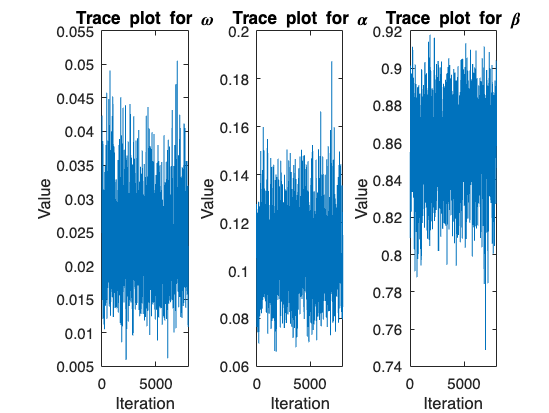

rng(2023);
dim = 3;
Niter = 10000;

% Initialize the Markov chain
markov_chain = zeros(Niter, dim);

% Draw the initial theta from the prior distributions
alpha_0 = betarnd(1.5, 10); % Initial alpha from its prior
beta_0 = betarnd(10, 1.5);  % Initial beta from its prior
omega_0 = abs(randn); % Initial omega (w > 0, so we take absolute value to ensure positivity)

theta_0 = [omega_0, alpha_0, beta_0]; % Combine into initial parameter vector
markov_chain(1,:) = theta_0; % Set the first element of the chain to theta_0

n = 1; % Start the counter
while n < Niter
    % Adaptive proposal variance
    if n <= 1000
        Sigma = .1^2 / dim * eye(dim); % Initial covariance matrix
    else
        Sigma = 2.38^2 / dim * cov(markov_chain(n-1000:n, :)); % Updated covariance
    end
    % Generate a new proposal point
    epsilon = mvnrnd(zeros(dim, 1), Sigma);
    proposal = markov_chain(n, :) + epsilon;
    % Compute the acceptance ratio
    auxiliary = log_posterior(proposal, y_t) - log_posterior(markov_chain(n, :), y_t);
    alpha = min(exp(auxiliary), 1);

    % Randomly decide whether to accept the new point
    u = rand;
    if u < alpha
        markov_chain(n+1, :) = proposal;
    else
        markov_chain(n+1, :) = markov_chain(n, :);
    end
    n = n + 1;  % Move to the next iteration
end

% Visualisation
Nburnin = 2000;
markov_chain_burnin = markov_chain(Nburnin+1:Niter,:);

omega = markov_chain_burnin(:, 1);
alpha = markov_chain_burnin(:, 2);
beta = markov_chain_burnin(:, 3);

subplot(1, 3, 1);
plot(omega);  % Plotting the first parameter
title('Trace plot for \omega');
xlabel('Iteration');
ylabel('Value');

subplot(1, 3, 2);
plot(alpha);  % Plotting the second parameter
title('Trace plot for \alpha');
xlabel('Iteration');
ylabel('Value');

subplot(1, 3, 3);
plot(beta);  % Plotting the third parameter
title('Trace plot for \beta');
xlabel('Iteration');
ylabel('Value');


% Estimates
post_mean_omega = mean(omega)

post_mean_omega = 0.0243

post_std_omega = std(omega)

post_std_omega = 0.0062


post_mean_alpha = mean(alpha)

post_mean_alpha = 0.1078

post_std_alpha = std(alpha)

post_std_alpha = 0.0156


post_mean_beta = mean(beta)

post_mean_beta = 0.8590

post_std_beta = std(beta)

post_std_beta = 0.0215

#### 2.1.2 With transformation

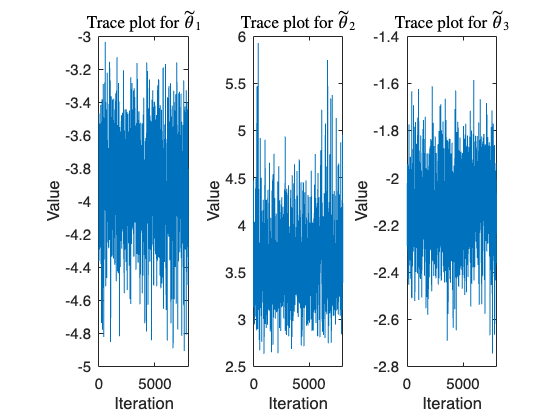

rng(2023);
% Initialize the Markov chain again
markov_chain = zeros(Niter, dim);

% Draw the initial thetas
theta_0 = randn(1,dim); % starting value under flat priors
markov_chain(1,:) = theta_0; % Set the first element of the chain to theta_0

n = 1; % Start the counter
while n < Niter
    % Adaptive proposal variance
    if n <= 1000
        Sigma = .1^2 / dim * eye(dim); % Initial covariance matrix
    else
        Sigma = 2.38^2 / dim * cov(markov_chain(n-1000:n, :)); % Updated covariance
    end
    % Generate a new proposal point
    epsilon = mvnrnd(zeros(dim, 1), Sigma);
    proposal = markov_chain(n, :) + epsilon;
    % Compute the acceptance ratio
    auxiliary = loglik_trans(proposal, y_t) - loglik_trans(markov_chain(n, :), y_t);
    alpha = min(exp(auxiliary), 1);

    % Randomly decide whether to accept the new point
    u = rand;
    if u < alpha
        markov_chain(n+1, :) = proposal;
    else
        markov_chain(n+1, :) = markov_chain(n, :);
    end
    n = n + 1;  % Move to the next iteration
end

% Visualisation A
Nburnin = 2000;
markov_chain_burnin = markov_chain(Nburnin+1:Niter,:);

subplot(1, 3, 1);
plot(markov_chain_burnin(:, 1));  % Plotting the first transformed parameter
title('Trace plot for $\tilde{\theta}_1$','Interpreter','latex');
xlabel('Iteration');
ylabel('Value');

subplot(1, 3, 2);
plot(markov_chain_burnin(:, 2));  % Plotting the second transformed parameter
title('Trace plot for $\tilde{\theta}_2$','Interpreter','latex');
xlabel('Iteration');
ylabel('Value');

subplot(1, 3, 3);
plot(markov_chain_burnin(:, 3));  % Plotting the third transformed parameter
title('Trace plot for $\tilde{\theta}_3$','Interpreter','latex');
xlabel('Iteration');
ylabel('Value');

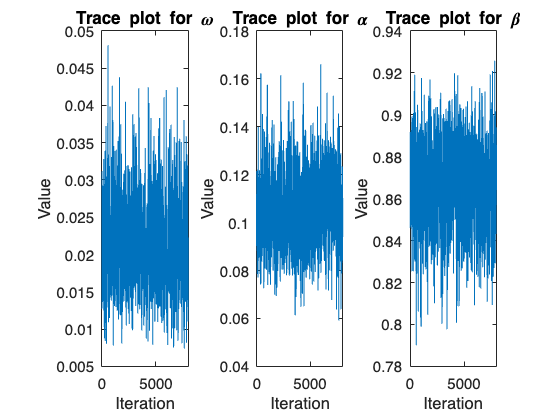


%% Posterior estimate for the original params
omega_trans = zeros(1,length(markov_chain_burnin));
alpha_trans = zeros(1,length(markov_chain_burnin));
beta_trans = zeros(1,length(markov_chain_burnin));

% Reverse transformation of unconstrained params to original params
for i = 1:length(markov_chain_burnin)
    theta = markov_chain_burnin(i,:);
    theta1 = theta(1);
    theta2 = theta(2);
    theta3 = theta(3);
    omega_trans(i) = exp(theta1);
    alpha_trans(i) = exp(theta2)*exp(theta3)/(1+exp(theta2)+exp(theta3)+exp(theta2)*exp(theta3));
    beta_trans(i) = exp(theta2)/(1+exp(theta2)+exp(theta3)+exp(theta2)*exp(theta3));
end

% Visualisation B
figure;
subplot(1, 3, 1);
plot(omega_trans);  % Plotting the first parameter
title('Trace plot for \omega');
xlabel('Iteration');
ylabel('Value');

subplot(1, 3, 2);
plot(alpha_trans);  % Plotting the second parameter
title('Trace plot for \alpha');
xlabel('Iteration');
ylabel('Value');

subplot(1, 3, 3);
plot(beta_trans);  % Plotting the third parameter
title('Trace plot for \beta');
xlabel('Iteration');
ylabel('Value');


% Estimates
post_mean_omega_trans = mean(omega_trans)

post_mean_omega_trans = 0.0212

post_std_omega_trans = std(omega_trans)

post_std_omega_trans = 0.0058


post_mean_alpha_trans = mean(alpha_trans)

post_mean_alpha_trans = 0.1048

post_std_alpha_trans = std(alpha_trans)

post_std_alpha_trans = 0.0149


post_mean_beta_trans = mean(beta_trans)

post_mean_beta_trans = 0.8671

post_std_beta_trans = std(beta_trans)

post_std_beta_trans = 0.0198

### 2.2 Variational Bayes

% Gaussian VB trial 
rng(2023);

n = length(y_t);
d = 3;   % Number of estimated parameters

% Prepare theta
trans_theta = rand(d,1);
L = 0.1*eye(d); 
dim = d + d*(d+1)/2;

% Initial variational mean
lambda = [trans_theta; vech(L)]; % initial lambda

% Set up 
S = 50; % Number of Monte Carlo samples
beta1_adap_weight = 0.9; % Adaptive learning weights
beta2_adap_weight = 0.9;
eps0 = 0.002; % Learning rate 
patience_max = 20; % Maximum patience parameter
max_iter = 5000; % Maximum number of iterations
tau_threshold = max_iter/2; % Threshold
t_w = 10; % Window size 
norm_gradient_threshold = 10;

grad_LB = zeros(S,dim);
h_lambda = zeros(S,1);
rqmc = normrnd(0,1,S,d);

for s = 1:S
    varepsilon = rqmc(s,:)'; 
    params = trans_theta+L*varepsilon; 
    [grad_h_lambda, h_lambda_return] = grad_h_function(params,y_t,trans_theta,L,n);
    grad_LB(s,:) = [grad_h_lambda;vech(grad_h_lambda*(varepsilon'))]';
    h_lambda(s) = h_lambda_return;
end
grad_LB = mean(grad_LB)';
LB = mean(h_lambda);

% gradient clipping
grad_norm = norm(grad_LB);
if norm(grad_LB)>norm_gradient_threshold
    grad_LB = (norm_gradient_threshold/grad_norm)*grad_LB;
end
g_adaptive = grad_LB; v_adaptive = g_adaptive.^2;
g_bar_adaptive = g_adaptive; v_bar_adaptive = v_adaptive;
iter = 1;
stop = false;
LB_bar = 0; patience = 0;

while ~stop
    mu = lambda(1:d);
    L = vechinv(lambda(d+1:end),2);
    grad_LB = zeros(S,dim);
    h_lambda = zeros(S,1);
    rqmc = normrnd(0,1,S,d);
    for s = 1:S
        varepsilon = rqmc(s,:)';
        params = mu+L*varepsilon;
        [grad_h_lambda,h_lambda_return] = grad_h_function(params,y_t,mu,L,n);
        grad_LB(s,:) = [grad_h_lambda;vech(grad_h_lambda*(varepsilon'))]';
        h_lambda(s) = h_lambda_return;
    end
    grad_LB = mean(grad_LB)';

    % gradient clipping
    grad_norm = norm(grad_LB);
    if norm(grad_LB)>norm_gradient_threshold
        grad_LB = (norm_gradient_threshold/grad_norm)*grad_LB;
    end

    g_adaptive = grad_LB; v_adaptive = g_adaptive.^2;
    g_bar_adaptive = beta1_adap_weight*g_bar_adaptive+(1- ...
        beta1_adap_weight)*g_adaptive;
    v_bar_adaptive = beta2_adap_weight*v_bar_adaptive+(1- ...
        beta2_adap_weight)*v_adaptive;
    if iter>=tau_threshold
        stepsize = eps0*tau_threshold/iter;
    else
        stepsize = eps0;
    end
    
    lambda = lambda+stepsize*g_bar_adaptive./sqrt(v_bar_adaptive);
    LB(iter) = mean(h_lambda);
    
    if iter>=t_w
        LB_bar(iter-t_w+1) = mean(LB(iter-t_w+1:iter));
        disp(['Iteration: ',num2str(iter), ' | Lowerbound smooth:',num2str(LB_bar(iter-t_w+1))]);
    else
        disp(['Iteration: ',num2str(iter), ' | Lowerbound smooth:',num2str(LB(iter))]);
    end
    
    if (iter>t_w)&&(LB_bar(iter-t_w+1)>=max(LB_bar))
        lambda_best = lambda;
        patience = 0;
    else
        patience = patience+1;
    end
    if (patience>patience_max)||(iter>max_iter) stop = true; end
    iter = iter+1;
end

Iteration: 1 | Lowerbound smooth:-3879.2958
Iteration: 2 | Lowerbound smooth:-3851.8504
Iteration: 3 | Lowerbound smooth:-3872.1779
Iteration: 4 | Lowerbound smooth:-3862.8203
Iteration: 5 | Lowerbound smooth:-3874.1213
Iteration: 6 | Lowerbound smooth:-3870.6614
Iteration: 7 | Lowerbound smooth:-3872.8199
Iteration: 8 | Lowerbound smooth:-3868.8013
Iteration: 9 | Lowerbound smooth:-3845.4254


Iteration: 10 | Lowerbound smooth:-3865.3416
Iteration: 11 | Lowerbound smooth:-3862.5511
Iteration: 12 | Lowerbound smooth:-3862.782
Iteration: 13 | Lowerbound smooth:-3859.7315
Iteration: 14 | Lowerbound smooth:-3858.8802
Iteration: 15 | Lowerbound smooth:-3854.4084
Iteration: 16 | Lowerbound smooth:-3850.1557
Iteration: 17 | Lowerbound smooth:-3847.8164
Iteration: 18 | Lowerbound smooth:-3844.6224
Iteration: 19 | Lowerbound smooth:-3845.6937
Iteration: 20 | Lowerbound smooth:-3842.4318
Iteration: 21 | Lowerbound smooth:-3841.2112
Iteration: 22 | Lowerbound smooth:-3839.0968
Iteration: 23 | Lowerbound smooth:-3838.7785
Iteration: 24 | Lowerbound smooth:-3834.0731
Iteration: 25 | Lowerbound smooth:-3833.5026
Iteration: 26 | Lowerbound smooth:-3831.9975
Iteration: 27 | Lowerbound smooth:-3829.6491
Iteration: 28 | Lowerbound smooth:-3827.802
Iteration: 29 | Lowerbound smooth:-3825.0487
Iteration: 30 | Lowerbound smooth:-3823.8037
Iteration: 31 | Lowerbound smooth:-3821.1306
Iteration: 3


lambda = lambda_best;
mu_vb = lambda(1:d);
L = vechinv(lambda(d+1:end),2);
Sigma = L*(L');
sigma2_vb = diag(Sigma);

omega_vb = exp(mu_vb(1))

omega_vb = 0.0225

alpha_vb = exp(mu_vb(2))*exp(mu_vb(3))/(1 + exp(mu_vb(2)) + exp(mu_vb(3)) + exp(mu_vb(2))*exp(mu_vb(3)))

alpha_vb = 0.1047

beta_vb = exp(mu_vb(2))/(1 + exp(mu_vb(2)) + exp(mu_vb(3)) + exp(mu_vb(2))*exp(mu_vb(3)))

beta_vb = 0.8642

figure; 
plot(1:4992,LB_bar,'LineWidth',1.5)

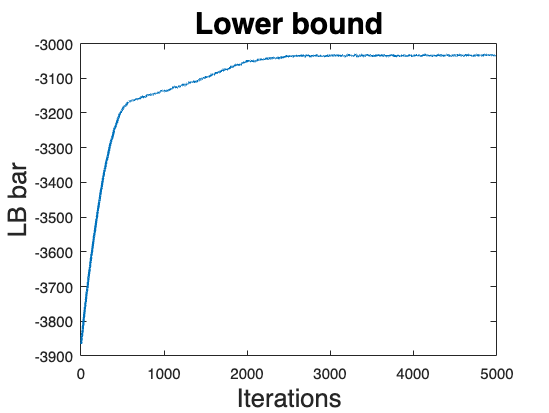

title('Lower bound','FontSize', 20)
xlabel('Iterations', 'FontSize', 17);
ylabel('LB bar', 'FontSize', 17);

## 3 Prediction

% get relevant observations
idx = find(data.Date=='28-June-2022');

% using MCMC no transformation
sigma2_pred = zeros(idx,1);
sigma2_pred(1) = var(y_t);

for t = 2:idx
    sigma2_pred(t) = post_mean_omega + post_mean_alpha*(y_t(t-1)^2) + post_mean_beta*sigma2_pred(t-1);
end

vol_forecast = sqrt(post_mean_omega + post_mean_alpha*(y_t(idx)^2) + post_mean_beta*sigma2_pred(idx))
 
% using MCMC with transformation
sigma2_pred_trans = zeros(idx,1);
sigma2_pred_trans(1) = var(y_t);

for t = 2:idx
    sigma2_pred_trans(t) = post_mean_omega_trans + post_mean_alpha_trans*(y_t(t-1)^2) + post_mean_beta_trans*sigma2_pred_trans(t-1);
end

vol_forecast_trans = sqrt(post_mean_omega_trans + post_mean_alpha_trans*(y_t(idx)^2) + post_mean_beta_trans*sigma2_pred_trans(idx))

% using VB
sigma2_pred_vb = zeros(idx,1);
sigma2_pred_vb(1) = var(y_t);

for t = 2:idx
    sigma2_pred_vb(t) = omega_vb + alpha_vb*(y_t(t-1)^2) + beta_vb*sigma2_pred_vb(t-1);
end

vol_forecast_vb = sqrt(omega_vb + alpha_vb*(y_t(idx)^2) + beta_vb*sigma2_pred_vb(idx))

model = garch(1,1);
mle = estimate(model,y_t);
vol_mle = sqrt(forecast(mle,1,y_t))